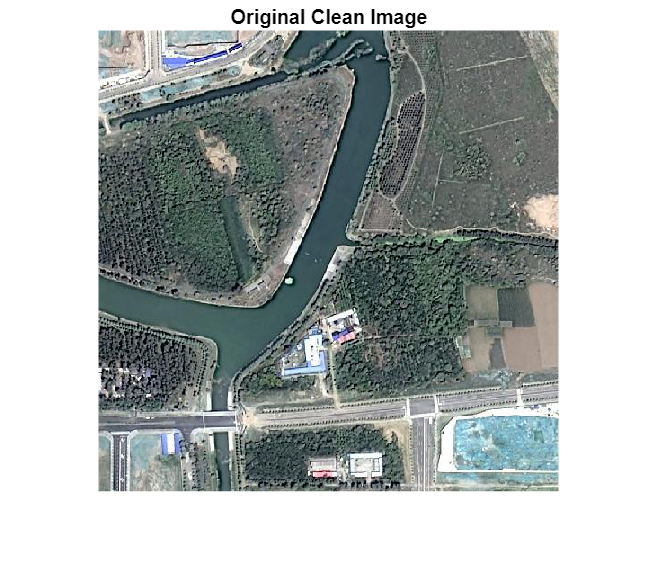

clc; clear; close all;

% READ CLEAN IMAGE
J_clean = im2double(imread("D:\Downloads\Haze1k\Haze1k\Haze1k_thin\dataset\train\target\35-targets.png"));
[h,w,~] = size(J_clean);

figure; imshow(J_clean);
title('Original Clean Image');

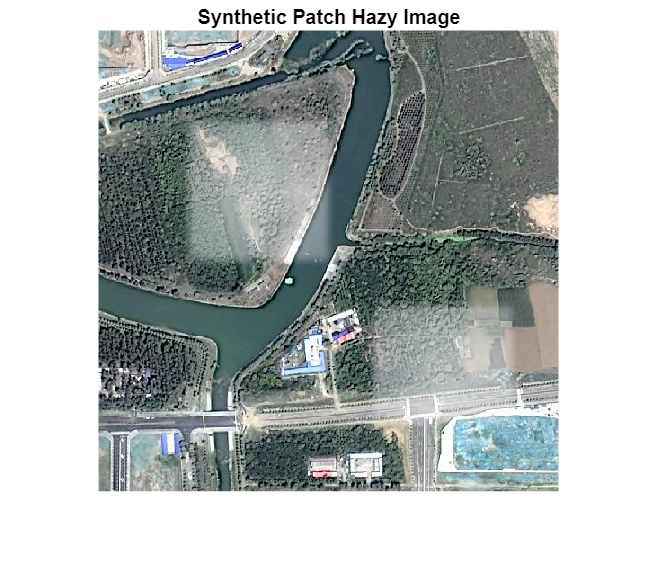


% CREATE PATCH-WISE SYNTHETIC HAZE
A_true = [1 1 1];
t_true = ones(h,w);

r1 = round(0.2*h); r2 = round(0.5*h);
c1 = round(0.2*w); c2 = round(0.5*w);

r3 = round(0.6*h); r4 = round(0.85*h);
c3 = round(0.6*w); c4 = round(0.9*w);

% Patch 1 radial transmission
[X1,Y1] = meshgrid(c1:c2, r1:r2);
cx1 = mean([c1 c2]); cy1 = mean([r1 r2]);
dist1 = sqrt((X1-cx1).^2 + (Y1-cy1).^2);
dist1 = dist1 / max(dist1(:));
t_patch1 = 0.4 + 0.3*dist1;
t_true(r1:r2,c1:c2) = t_patch1;

% Patch 2
[X2,Y2] = meshgrid(c3:c4, r3:r4);
cx2 = mean([c3 c4]); cy2 = mean([r3 r4]);
dist2 = sqrt((X2-cx2).^2 + (Y2-cy2).^2);
dist2 = dist2 / max(dist2(:));
t_patch2 = 0.4 + 0.3*dist2;
t_true(r3:r4,c3:c4) = t_patch2;

% Smooth transmission
t_true = imgaussfilt(t_true,4);

% Generate hazy image
I = zeros(h,w,3);
for c = 1:3
    I(:,:,c) = J_clean(:,:,c).*t_true + A_true(c)*(1-t_true);
end

figure; imshow(I);
title('Synthetic Patch Hazy Image');

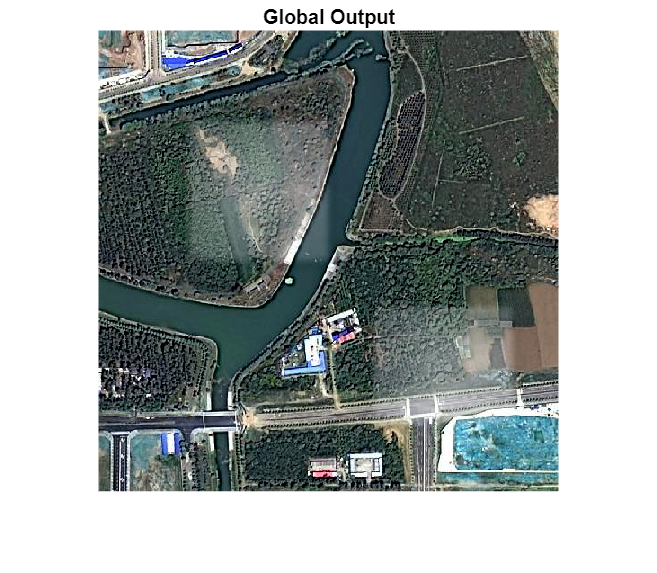


% DEHAZING (GLOBAL PROCESSING)

% Atmospheric Light
I_gray = rgb2gray(I);
sortedPixels = sort(I_gray(:),'descend');
topPixels = sortedPixels(1:round(0.001*numel(sortedPixels)));
A_gray = mean(topPixels);
A = [A_gray A_gray A_gray];

% Dark channel transmission
dark_channel = min(I,[],3);
W = fspecial('average',[15 15]);
dark_blur = imfilter(dark_channel, W, 'replicate');

omega = 0.95;
t0 = 1 - omega * dark_blur;
t0 = min(max(t0,0.1),0.95);

% Multi-sample restoration
numSamples = 4;
blurSet = [5 11 21 31];
lambdaSet = [0.05 0.08 0.12 0.16];

Jset = zeros(h,w,3,numSamples);

for k = 1:numSamples
    
    Wk = fspecial('average',[blurSet(k) blurSet(k)]);
    dark_k = imfilter(dark_channel, Wk, 'replicate');
    tk = 1 - omega * dark_k;
    tk = min(max(tk,0.1),0.95);
    
    lambda = lambdaSet(k);
    H_pinv = tk ./ (tk.^2 + lambda + eps);
    
    for c = 1:3
        Jset(:,:,c,k) = H_pinv .* (I(:,:,c) - A(c)) + A(c);
    end
    
    Jset(:,:,:,k) = min(max(Jset(:,:,:,k),0),1);
end

% Frequency fusion
Ffused = zeros(h,w,3);

for c = 1:3
    Fsum = zeros(h,w);
    for k = 1:numSamples
        Fsum = Fsum + fft2(Jset(:,:,c,k));
    end
    Ffused(:,:,c) = real(ifft2(Fsum / numSamples));
end

Ffused = min(max(Ffused,0),1);

figure; imshow(Ffused);
title('Global Output');

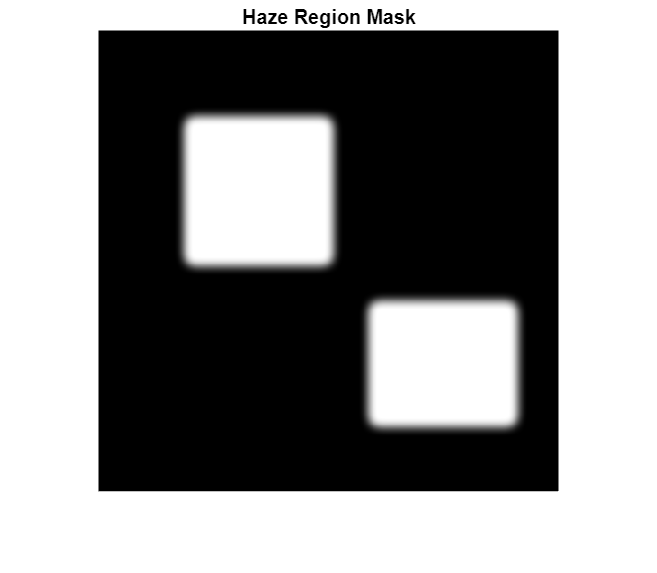


% PATCH-ONLY BLENDING

hazeMask = t_true < 0.98;          
hazeMask = imgaussfilt(double(hazeMask),5);  

figure; imshow(hazeMask,[]);
title('Haze Region Mask');

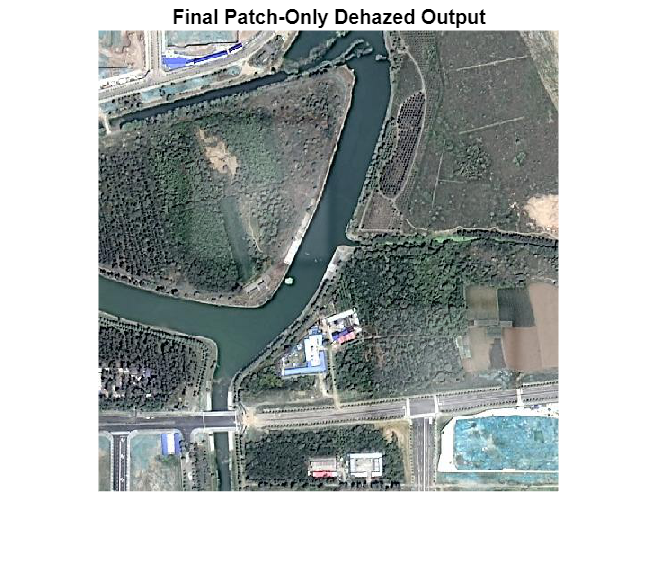


J_final = zeros(h,w,3);

for c = 1:3
    J_final(:,:,c) = ...
        hazeMask .* Ffused(:,:,c) + ...
        (1-hazeMask).*I(:,:,c);
end

J_final = min(max(J_final,0),1);

figure; imshow(J_final);
title('Final Patch-Only Dehazed Output');


imwrite(J_final,'patch_only_dehazed.png');

% FROBENIUS NORM

norm_input = norm(I,'fro');
norm_output = norm(J_final,'fro');
norm_removed = norm(I - J_final,'fro');

disp(' ');

disp('===== FROBENIUS NORM ANALYSIS =====');

===== FROBENIUS NORM ANALYSIS =====


disp(['Input        : ', num2str(norm_input)]);

Input        : 474.7369


disp(['Output       : ', num2str(norm_output)]);

Output       : 444.4685


disp(['Haze Removed : ', num2str(norm_removed)]);

Haze Removed : 67.9017


disp(['Haze Reduction %  : ', num2str((norm_removed/norm_input)*100)]);

Haze Reduction %  : 14.303
